#### Sample code to add a channel mesh to an existing background mesh

Load dependent packages

% OceanMesh2D - Customize for your installation
OM2DDIR = 'Y:/home/sbunya/GitHub';
addpath([OM2DDIR '/OceanMesh2D/'])

addpath(genpath([OM2DDIR '/OceanMesh2D/utilities/']))
addpath(genpath([OM2DDIR '/OceanMesh2D/datasets/']))
addpath(genpath([OM2DDIR '/OceanMesh2D/m_map/']))
addpath(genpath([OM2DDIR '/OceanMesh2D/OceanMesh2D_Datasets/tpxo9_netcdf/']))

% mesh2d - Customize for your installation
MESH2DDIR = 'Y:/home/sbunya/GitHub';
addpath([MESH2DDIR '/mesh2d']);     % Customize this for your mesh2d installation
initmsh();

Add path to matlab programs

addpath('Y:/home/sbunya/GitHub/adcircutils/src/adcircutils/channelpaving')

Change the current working directory

cwd = 'Y:/home/sbunya/GitHub/adcircutils/examples/channelpaving';
cd(cwd)   % Customize this for your installation

Setting parameters

% 
% --- Frequently customized parameters
%
pave_opts.editname = 'roanoke';     % Name of the channel of the current interest.
in14 = [cwd '/input/ncv30.00c.grd'];     % Background mesh file
pave_opts.in14 = in14;
in13 = [cwd '/input/ncv30.00c.13'];      % Background mesh nodal attribute file
pave_opts.in13 = in13;
pave_opts.flowlinefile = [cwd '/output/nhdp_hr_sample_roanoke_1_DP_WD.geojson'];
                                    % Geospatial file to specify flow lines and channel attributes
pave_opts.output_id = 'ncv30.01a';
pave_opts.output_mesh_prefix = [cwd './output/' pave_opts.output_id];
                                    % Prefix of the output mesh file 
pave_opts.radius_to_merge_shppoints = 0.1;
                                    % distatance threshold in m. to determine points 
                                    % in flow centerlines to be merged
pave_opts.resolution = 80.0;        % Node spacing along channel
pave_opts.min_spacing = 40;         % Minimum nocal spacing. Generated nodes along channels will be thinned out if
                                    % the nodal distance becomes less than this number.
pave_opts.removal_range = 4000/pave_opts.resolution; 
                                    % Distance from the flowlines within which the background mesh 
                                    % is replaced with a new channel mesh and a gap-filling mesh.
                                    % Specified as a ratio to along-channel 'resolution.' 
pave_opts.max_channel_depth = 10.5; % Maximum channel bed depth positive downward relative to datum
pave_opts.min_channel_depth = 2.0;  % Minimum depth of channels relative to the banks
pave_opts.max_width = 10000.0;      % Maximum channel width
pave_opts.min_width = 10.0;         % Minimum channel width
pave_opts.min_condensed_nodes_spacing = 40.0;
                                    % Threshold distance in meters between paired nodes on the sides of a
                                    % channel. If the distance between these nodes are less than this
                                    % number, condensed_nodes nodal attrubites are set for the pair
                                    % to avoid violating the CFL condition.
pave_opts.set_initial_river_elevation = true;
                                    % Flag to set the nodal attribute, "initial_river_elevation"
pave_opts.zshift = 0.0;             % This value is added to the specified depth to uniformly lift 
                                    % channel beds
pave_opts.zshift_taper_elev_range = [0.0 0.0];
                                    % Elevation range to taper the zshift
pave_opts.diffuse_depth = true;     % Flag to diffuse depth to the reaches where no depths are given
pave_opts.diffuse_width = true;     % Flag to diffuse width to the reaches where no widths are given
pave_opts.plot_level = 0;           % Control for plotting levels...0: Minimum plots, 1-2: More plots
pave_opts.write_output = true;     % Flag to output the resulting mesh and nodal attribute to files 
                                    % at the end of a function call.
pave_opts.indomain_flowbc = true;   % Flag to set flow boundaries at the upstream ends of the channels
pave_opts.do_renum = false;         % Flag to renumber the updated mesh at the end of a function call

% Channel nodal attribute values
keys = ["mannings_n_at_sea_floor", ...
        "primitive_weighting_in_continuity_equation"];
defvalues = {0.02,0.03};
channelvalues = {0.02,0.1};
pave_opts.default_ndattrs = dictionary(keys,defvalues);
pave_opts.channel_ndattrs = dictionary(keys,channelvalues);

% 
% --- Rarely customized parameters
%                                    
pave_opts.channel_smoothing_span = 3;
                                    % Smoothing parameter for width and depth. No smoothing applied if the value is 1 
pave_opts.spacing_link_with_width = false;
                                    % Flag to adapt nodal spacing along channel with width
pave_opts.effective_width_ratio = 1.0;
                                    % Effective width ratio, which is multiplied with the specified width values
pave_opts.rep_dist_adjust = 1.0;    % Adjustment scale for the local representative mesh size
pave_opts.rseed = 1;                % Random seed
pave_opts.ignore_depth_in_channel = true; 
                                    % Flag to decide if the depth along the channels should be ignored 
                                    % when the depths on the banks and floodplains are interpolated from 
                                    % the background mesh.
pave_opts.nudge_depth_at_channel_ends = false; 
                                    % Flag to not exclude original mesh depths at the end of channels 
                                    % when interpolating the depths at floodplain nodes
pave_opts.no_channelmesh = false;   % Flag to not use the channel mesh
pave_opts.set_initial_river_elevation = true;
                                    % Flag to set the nodal attribute, "initial_river_elevation"
pave_opts.reject_margin = 0.0;      % [NOT USED] The ratio to the representative original mesh element size to be used for rejection judgement
pave_opts.max_num_rejected = 10000; % [NOT USED] Maximum number of rejections of the randomly generated nodes
pave_opts.niter_relax = 10;         % [NOT USED] Number of mesh relaxation iteration
pave_opts.dem = [];                 % [NOT USED] DEM file to be used to determine channel depths

% Print it for confirmation
pave_opts

pave_opts = struct with fields:
                       editname: 'roanoke'
                           in14: 'Y:/home/sbunya/GitHub/adcircutils/examples/channelmodeling/channelpaving/example1/input/ncv30.00c.grd'
                           in13: 'Y:/home/sbunya/GitHub/adcircutils/examples/channelmodeling/channelpaving/example1/input/ncv30.00c.13'
                   flowlinefile: 'Y:/home/sbunya/GitHub/adcircutils/examples/channelmodeling/channelpaving/example1/output/nhdp_hr_sample_roanoke_1_DP_WD.geojson'
             output_mesh_prefix: 'Y:/home/sbunya/GitHub/adcircutils/examples/channelmodeling/channelpaving/example1./output/ncv30.01a'
      radius_to_merge_shppoints: 0.1000
                     resolution: 80
                    min_spacing: 40
                  removal_range: 50
              max_channel_depth: 10.5000
              min_channel_depth: 2
                      max_width: 10000
                      min_width: 10
    min_condensed_nodes_spacing: 40
    set_initial_riv

Read the background mesh

m_bg = msh('fname',in14,'aux',{in13});

INFO: An ADCIRC fort.14 file will be read...
read adcirc fort.14
ncv27.05ca1 based, Roanoke River upstream floodplain added
INFO: ADCIRC fort.13 file will be read...
ncv27.05ca1 based, Roanoke River upstream floodplain added
surface_directional_effective_roughness_length
surface_canopy_coefficient
mannings_n_at_sea_floor
primitive_weighting_in_continuity_equation
average_horizontal_eddy_viscosity_in_sea_water_wrt_depth
elemental_slope_limiter
wave_refraction_in_swan
sea_surface_height_above_geoid
initial_river_elevation
overland_reduction_factor
advection_state
condensed_nodes


Pave channels in the background mesh

Timer: 1
Elapsed time is 2.809680 seconds.
Timer: 2
Elapsed time is 0.227850 seconds.
Timer: 2
Elapsed time is 0.919293 seconds.
Timer: 4
Elapsed time is 0.001689 seconds.
Timer: 5
Elapsed time is 0.899887 seconds.
diffusing depth ... loopcnt = 1, anynan_cnt = 22
Timer: 6
Elapsed time is 10.876454 seconds.
Timer: 7
Elapsed time is 9.813957 seconds.
Timer: 8
Elapsed time is 0.043692 seconds.
Timer: 9
Elapsed time is 0.455294 seconds.
Checking if there is any intersecting edges...
No intersecting edge found. Proceeding...
Timer: 10
Elapsed time is 34.847708 seconds.
Timer: 11-1
Elapsed time is 0.946474 seconds.
Timer: 11-2
Elapsed time is 0.064754 seconds.
Timer: 11
Elapsed time is 0.013269 seconds.
       12011           2       12011           1

Writing a channel mesh to file: Y:/home/sbunya/GitHub/adcircutils/examples/channelmodeling/channelpaving/example1./output/ncv30.01a_roanoke_mch.14
write adcirc fort.14
OceanMesh2D
Timer: 12
Elapsed time is 0.215066 seconds.
Timer: 12.3
Elapsed

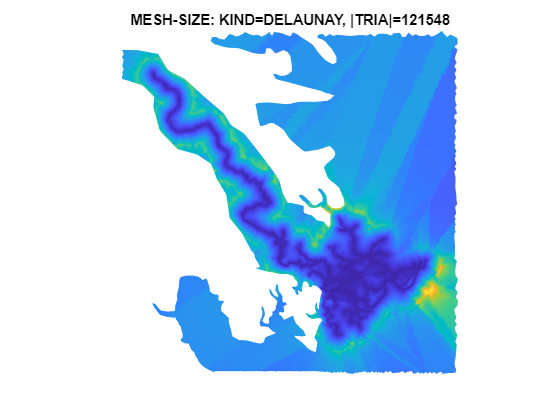


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10              11567             103887
         20              11567             149879
         30              11567             163155
         40              11567             167659
         50              11567             168731
         54              11567             168801



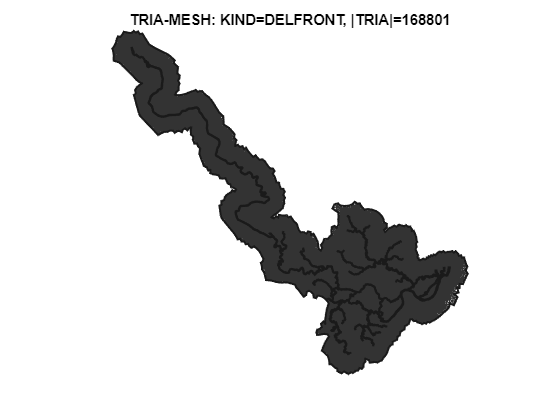

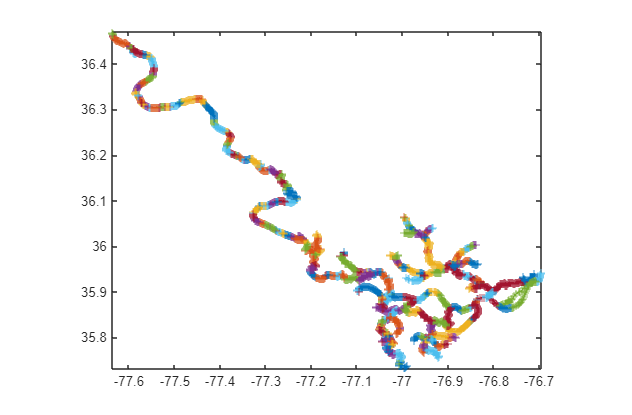

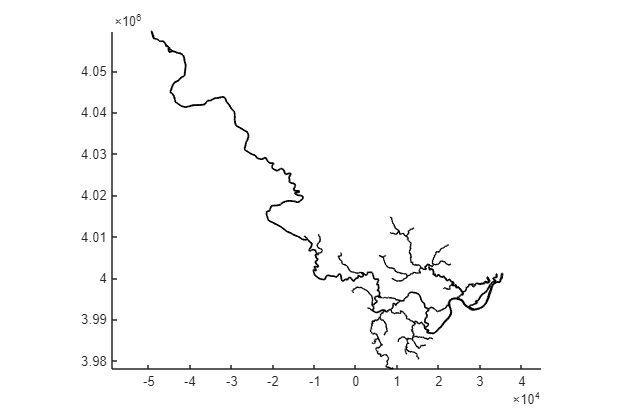

Timer: 15.5
Elapsed time is 35.538990 seconds.
Writing a connecting mesh to file: Y:/home/sbunya/GitHub/adcircutils/examples/channelmodeling/channelpaving/example1./output/ncv30.01a_roanoke_mconn.14
write adcirc fort.14
OceanMesh2D
Timer: 16
Elapsed time is 640.181502 seconds.
Timer: 16-1
Elapsed time is 0.100000 seconds.
Timer: 16-2
Elapsed time is 0.863658 seconds.
Timer: 17
Elapsed time is 560.964784 seconds.
Writing a mesh including the channels and the connecting area to file:Y:/home/sbunya/GitHub/adcircutils/examples/channelmodeling/channelpaving/example1./output/ncv30.01a_roanoke_mconnch.14
write adcirc fort.14
OceanMesh2D
Timer: 18
Elapsed time is 4.396535 seconds.
Timer: 19
Elapsed time is 605.853348 seconds.
Timer: 20
Elapsed time is 0.961221 seconds.
Timer: 21
Elapsed time is 0.468998 seconds.
Writing the final mesh with added channels to file: Y:/home/sbunya/GitHub/adcircutils/examples/channelmodeling/channelpaving/example1./output/ncv30.01a_roanoke.grd
write adcirc fort.14

m_new = msh_pave_channels(m_bg, pave_opts);

m_out = msh_renum_mesh_with_condensednodes(m_new);

Initial bandwidth is 735087
Renumbered bandwidth is 3589
Renumbering the elevation specified boundary nodestrings...
Renumbering the flux boundary nodestrings...
Renumbering the fort.13...



m_out.title = pave_opts.output_id;
m_out.f13.ARGID = ['Nodal attrs for ' pave_opts.output_mesh_prefix];

out14 = pave_opts.output_mesh_prefix;
m_out.write(out14,{'13','14'});

write adcirc fort.14
ncv30.01a


movefile([out14 '.14'],[out14 '.grd']);